# Getting Started with simurtools Toolbox

## Description

This toolbox provides utilities to deal with the typical problems we find at the SIMuR/Robotics Lab at the University of Oviedo, related to robotics and to analyze data captured with wearable sensors such as IMUs.

## System Requirements

Other toolboxes and Simulink are ocassionally used.  

## Features

The provided tools can be grouped in three categories:

- robotics

- human motion analysis

- general broad use tools

The firts group uses the Robotic Systems Toolbox from Matlab a lot, and robot models that are included.

The second group usually needs data from sensors. Examples are provided in the toolbox. 

## Examples

An example from the robotics tools subset, this is to draw a frame from the homogeneous matrix:

T0=eye(4);
pframe(T0,'c',1.4);
view(-60,30)

or we can get the symbolic forward kinematics of the irb-120 ABB robot:

T=kin_irb120(5)

from the human-motion section, we can detect gait events from COG accelerometry:

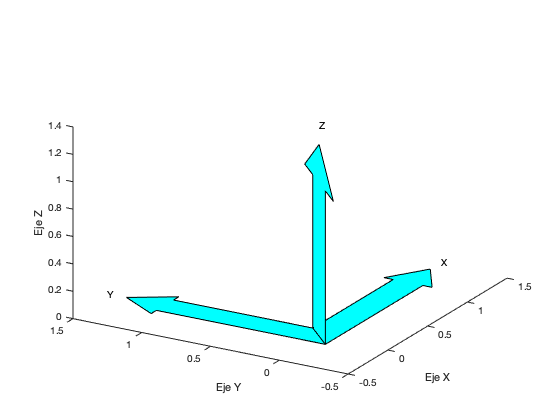

data=load('../simur_data/test.log');
Acc_X=data(:,4); 
Acc_Z=data(:,2);
tiempos=eventos_RT(0,0,'reset')
eventosHS=0*Acc_X;
eventosTO=0*Acc_X;
for k=1:length(Acc_X)
    [hs,to]=eventos_RT(Acc_X(k),Acc_Z(k));
    if (hs~=0)
        eventosHS(k-hs)=1;
    end

    if (to~=0)
        eventosTO(k-to)=1;
    end

end

and represent the output data:

figure; plot(Acc_X(1000:1300)); 
hold on; plot(Acc_Z(1000:1300),'r');
plot(eventosHS(1000:1300)*10,'c');
plot(eventosTO(1000:1300)*10,'k');


There is much more fun in the toolbox, just browse the examples data or just... enjoy !